clear;

% Global
load("HW1_data.mat");
xData = HW1_data.Xdata;
yData = HW1_data.Ydata;

xCoarse = -1 + (0:10)*6/10;

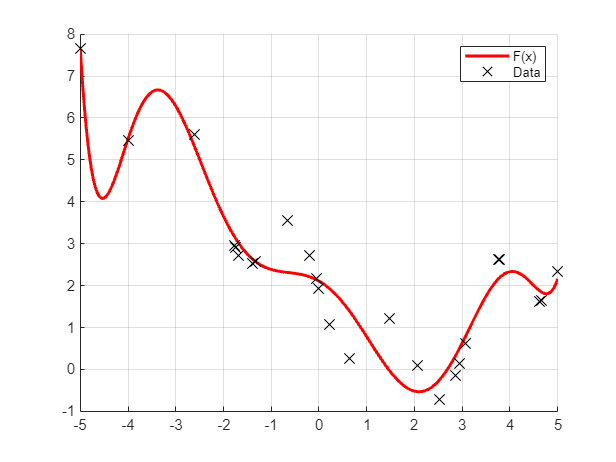

% Q2: Polynomial fitting
polyCoeff = PolynomialFit(xData, yData, 15);
xxQ2 = linspace(min(xData), max(xData), 256);
yyQ2 = polyval(polyCoeff, xxQ2);

f = figure();
grid on;
legend('Location', 'northeast');
xticks(-5:1:5);

hold on;
plot(xxQ2, yyQ2, 'r-', 'LineWidth', 2, ...
    'DisplayName', "F(x)");
plot(xData, yData, 'kx', 'MarkerSize', 10, ...
    'DisplayName', "Data");
hold off;

exportgraphics(f, [pwd '/Figures/HW1_q2.png'])

% Q3: Upper Bound
xxQ3 = linspace(-1, 5, 256);

Fp1 = polyder(polyCoeff)';
UB_11 = max(abs(polyval(Fp1, xxQ2)));
UB_12 = max(abs(polyval(Fp1, xxQ3)));

Fp2 = polyder(Fp1)';
UB_21 = max(abs(polyval(Fp2, xxQ2)));
UB_22 = max(abs(polyval(Fp2, xxQ3)));

Fp3 = polyder(Fp2)';
UB_31 = max(abs(polyval(Fp3, xxQ2)));
UB_32 = max(abs(polyval(Fp3, xxQ3)));

Fp4 = polyder(Fp3)';
UB_41 = max(abs(polyval(Fp4, xxQ2)));
UB_42 = max(abs(polyval(Fp4, xxQ3)));

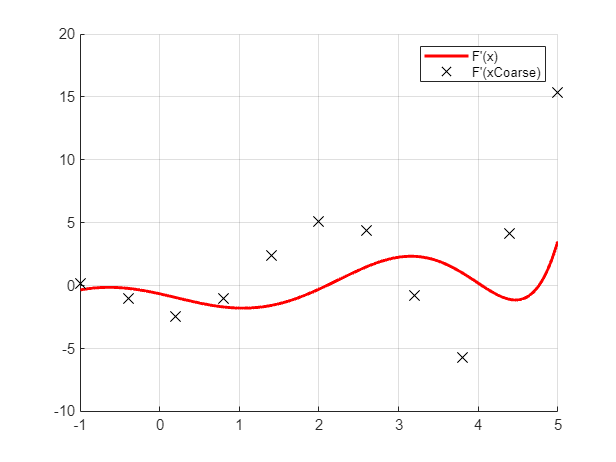

% Q4: Differencing
Fp_x0 = ( polyval(Fp1, xCoarse(2)) - polyval(Fp1, xCoarse(1)) ) * 5/3;
Fp_x10 = ( polyval(Fp1, xCoarse(11)) - polyval(Fp1, xCoarse(10)) ) * 10/3;
Fp_x = ( polyval(Fp1, xCoarse(3:11)) - polyval(Fp1, xCoarse(1:9)) ) * 5/3;

yyQ4 = polyval(Fp1, xxQ3);

f = figure();
grid on;
legend('Location', 'northeast');
xticks(-1:1:5); xlim([-1 5]);

hold on;
plot(xxQ3, yyQ4, 'r-', 'LineWidth', 2, ...
    'DisplayName', "F'(x)");
plot(xCoarse, [Fp_x0 Fp_x Fp_x10], 'kx', 'MarkerSize', 10, ...
    'DisplayName', "F'(xCoarse)");
hold off;

exportgraphics(f, [pwd '/Figures/HW1_q4.png'])

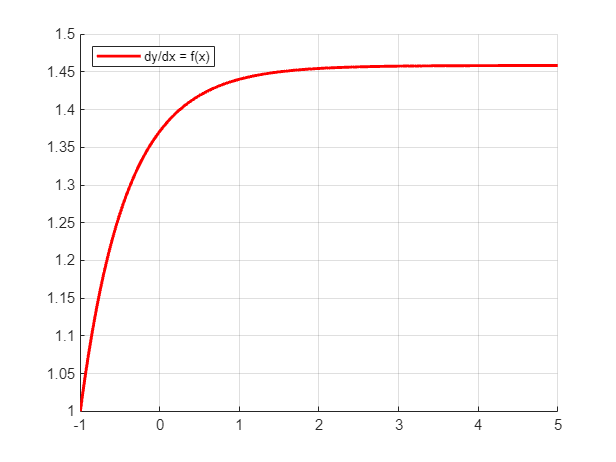

% Q6: IVP Solution
N = 200;
dt = 6/N;
t = -1:dt:5;
y = zeros(N+1, 1);
y(1) = 1;

for n = 1 : N
    y(n+1) = y(n) + dt*polyval(polyCoeff, y(n));
end

f = figure();
grid on;
legend('Location', 'northwest');
xticks(-1:1:5); xlim([-1 5]);

hold on;
plot(t, y, 'r-', 'LineWidth', 2, ...
    'DisplayName', "dy/dx = f(x)");
hold off;

exportgraphics(f, [pwd '/Figures/HW1_q6.png'])

% Q7
t075 = 0.75/dt;
y(t075)

ans = 1.3219

t37 = floor(3.7/dt);
y(t37)

ans = 1.4570